rrAppPath = "C:\Program Files\RoadRunner R2023b\bin\win64";
s = settings;
s.roadrunner.application.InstallationFolder.TemporaryValue = rrAppPath;
rrProj = "C:\Users\colli\Documents\College\MEEN 401 909 Intro to Mech Engr Design\Simulation\Test\Test";

rrApp=roadrunner(rrProj);
%rrApp=roadrunner(rrProj,NoDisplay=false);

openScenario(rrApp,"LeadCutIn3.rrscenario");

rrSim = rrApp.createSimulation

Connection status: 1
Connected to RoadRunner Scenario server on localhost:42012, with client id {bb77a9df-47a6-47c4-bb00-f6db826ab0f1}


rrSim =   ScenarioSimulation with no properties.


hdMap = getMap(rrSim);
lanes = hdMap.map.lanes;

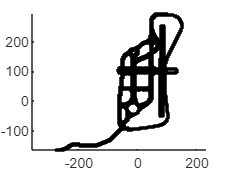

figure
hold on
for i =1:numel(lanes)
    control_points = lanes(i).geometry.values;
    x_coords = arrayfun(@(cp) cp.x,control_points);
    y_coords = arrayfun(@(cp) cp.y,control_points);
    plot(x_coords,y_coords, 'k.-');

end
axis equal

%set(rrSim,"SimulationCommand","Start");
%while strcmp(get(rrSim,"SimulationStatus"),"Running")
%    pause(1);
%end

%rrLog = get(rrSim,"SimulationLog");

%poseActor1 = rrLog.get('Pose','ActorID',1);
%positionActor1_x = arrayfun(@(x) x.Pose(1,4),poseActor1);
%positionActor1_y = arrayfun(@(x) x.Pose(2,4),poseActor1);
%plot(positionActor1_x,positionActor1_y,"r","LineWidth",2)
%
%poseActor2 = rrLog.get('Pose','ActorID',2);
%positionActor2_x = arrayfun(@(x) x.Pose(1,4),poseActor2);
%positionActor2_y = arrayfun(@(x) x.Pose(2,4),poseActor2);
%plot(positionActor2_x,positionActor2_y,"b","LineWidth",2)
%
%title("Agent Positions from RoadRunner Scenario")
%ylabel("Y (m)")
%xlabel("X (m)")

[nodeTable,edgeTable] = helperGetNodesEdges;

graph = navGraph(nodeTable,edgeTable);

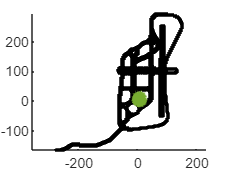

show(graph)

%egoStartPosition = getScenarioVariable(rrApp,"EgoInitialPosition");
%egoStartPosition = str2double(split(egoStartPosition,","))';
% My test thing
egoStartPosition = [17.3953000000000, 44.7025000000000,	235.573000000000];

egoGoalPosition = getScenarioVariable(rrApp,"Goal");
egoGoalPosition = str2double(split(egoGoalPosition,","))';
setScenarioVariable(rrApp,EgoGoalPosition=['[',num2str(egoGoalPosition),']']);

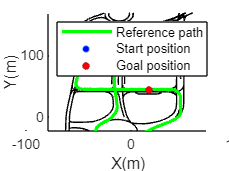

planner = plannerAStar(graph);
refPath = HelperPlanPath.planPath(planner,graph,egoStartPosition,egoGoalPosition);
pRefPath = plot(refPath(:,1),refPath(:,2),Color="g",LineWidth=2);
% Plot markers for start and goal positions
pStart = plot(egoStartPosition(1),egoStartPosition(2),"o",MarkerFaceColor="b",MarkerSize=4);
pEnd = plot(egoGoalPosition(1),egoGoalPosition(2),"o",MarkerFaceColor="r",MarkerSize=4);
% Add legends
legend([pRefPath pStart pEnd],{"Reference path","Start position","Goal position"},Location="northwest")

set(rrSim,SimulationCommand="Start")
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(0.01)
end

setScenarioVariable(rrApp,ChangeSpeed_TargetSpeed="18")

obstacleDistance = 50;
setScenarioVariable(rrApp,ReplanTriggerDistance=num2str(obstacleDistance));
setScenarioVariable(rrApp,ObstacleDistance=num2str(obstacleDistance));

set(rrSim,SimulationCommand="Start")
while strcmp(get(rrSim,"SimulationStatus"),"Running")
    pause(0.01) 
end

Error using Simulink.ScenarioSimulationMcos/get
Error in Scenario Server: Internal error occurred

Error in Simulink.ScenarioSimulation/get